clear all
close all
format long


**System parameters**

params.M_m = 0.251;
params.m = 0.179;
params.i = 0.792e-4;
params.I = 2.592e-4;
params.R = 0.06;
params.rho = 0.024;
params.g = 9.81;

[ a, b_0, b_1, c, d, g, R ] = params2p(params);


params.servo_0 = 0;
params.servo_1 = 0;
params.servo_2 = 0;
params.servo_3 = 0.001;
params.servo_4 = 0;
params.servo_5 = 0;
params.servo_6 = 0;


**Verification of **$\alpha \beta \gamma$** coefficients**

s = -pi:0.001:pi;

A = [];
B = [];
G = [];

[ alpha_fcn, beta_fcn, gamma_fcn ] = s_abg_analytics(params)

alpha_fcn = function_handle with value:
    @(s)cos(cos(s)./1.0e+3).*7.160000000000001e-2-(sin(s).*(cos(cos(s)./1.0e+3).*4.296e-3+1.7184e-3))./1.0e+3+3.23e+2./1.0e+3


beta_fcn = function_handle with value:
    @(s)cos(s).*(-1.7184e-6)-sin(cos(s)./1.0e+3).*sin(s).^2.*4.296e-9-cos(cos(s)./1.0e+3).*cos(s).*4.296e-6


gamma_fcn = function_handle with value:
    @(s)sin(cos(s)./1.0e+3).*7.02396e-1


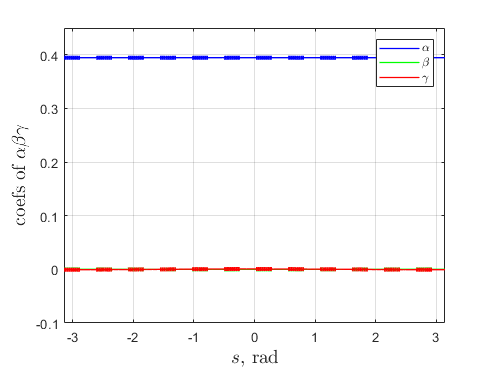


for i = 1 : length(s)
    [AA,BB,GG] = plot_abg(s(i), params);
    A = [A, AA];
    B = [B, BB];
    G = [G, GG];
end

figure()
plot(s,A,'-b',LineWidth=1.0)
hold on
plot(s,B,'-g',LineWidth=1.0)
plot(s,G,'-r',LineWidth=1.0)
grid on
plot(s, alpha_fcn(s),'--b',LineWidth=3.0)
hold on
plot(s, beta_fcn(s),'--g',LineWidth=3.0)
plot(s, gamma_fcn(s),'--r',LineWidth=3.0)

xlabel('$s$, rad',Interpreter='latex',FontSize=14);
ylabel('coefs of $\alpha \beta \gamma$',Interpreter='latex',FontSize=14)
legend('$\alpha$','$\beta$','$\gamma$','Interpreter','latex');
axis([ s(1) s(end) -0.1 0.45 ])

## Integration itself

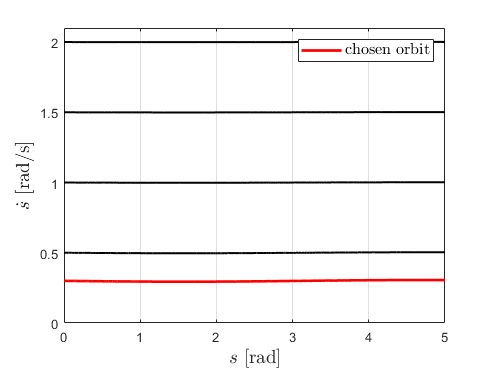

options = odeset('RelTol', 1e-12, 'AbsTol', 1e-16);
t_end = 4 * pi;
y_0 = [ 0; 2 ];
y_01 = [ 0; 0.3 ];
y_02 = [ 0; 1 ];


[ T1,  Y1 ] = ode89(@(t,y) abg_rhs(t,y,params), [0:0.001:t_end],  y_0, options);
[ T, Y ]    = ode89(@(t,y) abg_rhs(t,y,params), [0:0.001:4*t_end], y_01, options);
[ T2, Y2 ]  = ode89(@(t,y) abg_rhs(t,y,params), [0:0.001:t_end], y_02, options);

[ T3, Y3 ]  = ode89(@(t,y) abg_rhs(t,y,params), [0:0.001:t_end], [0; 0.5], options);
[ T4, Y4 ]  = ode89(@(t,y) abg_rhs(t,y,params), [0:0.001:t_end], [ 0; 1.5 ], options);

% [ T00, Y00 ] = ode89(@(t,y) rhs(t,y,params), [0:0.00001:t_end], y_01, options);

S = Y(:,1);
V = Y(:,2);

figure()
plot(S, V, '-r', LineWidth = 2.0)
hold on
plot(Y1(:,1), Y1(:,2), '-k', LineWidth=1.5)
plot(Y2(:,1), Y2(:,2), '-k', LineWidth=1.5)
plot(Y3(:,1), Y3(:,2), '-k', LineWidth=1.5)
plot(Y4(:,1), Y4(:,2), '-k', LineWidth=1.5)
% plot(Y00(:,1), Y00(:,2), '-b', LineWidth=1.5)

xlabel('$s$ [rad]',Interpreter='latex',FontSize=14)
ylabel('$\dot{s}$ [rad/s]',Interpreter='latex',FontSize=14)
axis([ 0 5.0 0 2.1 ])
grid on
legend("chosen orbit", '', '', '', '', 'FontSize', 12, 'interpreter', 'latex')

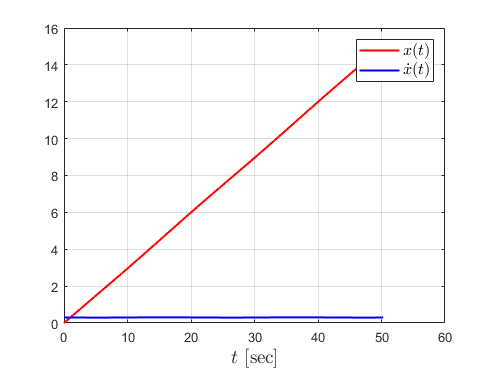


clear T1 T2 T3 T4 Y1 Y2 Y3 Y4 y_01 y_02 y_0

X = zeros(2,length(T));
Theta = zeros(2,length(T));

for i = 1 : length(T)
    [ Q, dQ, ddQ ] = servo(S(i), params);
    X(:,i) = [ Q(1); dQ(1) * V(i) ];
    Theta(:,i) = [ Q(2); dQ(2) * V(i) ];
end

figure()
plot(T, X(1,:), 'r', LineWidth=1.5)
hold on
plot(T, X(2,:), 'b', LineWidth=1.5)
xlabel('$t$ [sec]',Interpreter='latex',FontSize=14)
% ylabel('$\dot{s}$ [rad/s]',Interpreter='latex',FontSize=14)
grid on
legend('$x(t)$','$\dot{x}(t)$','FontSize',12,'interpreter','latex')

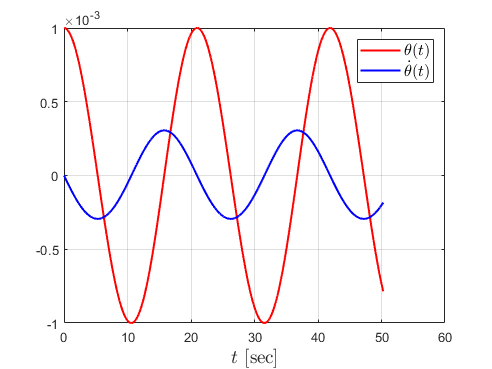


figure()
plot(T,Theta(1,:),'r',LineWidth=1.5)
hold on
plot(T,Theta(2,:),'b',LineWidth=1.5)
xlabel('$t$ [sec]',Interpreter='latex',FontSize=14)
% ylabel('$\dot{s}$ [rad/s]',Interpreter='latex',FontSize=14)
grid on
legend('$\theta(t)$','$\dot{\theta}(t)$','FontSize',12,'interpreter','latex')

## **Find signle periodic trajectory**

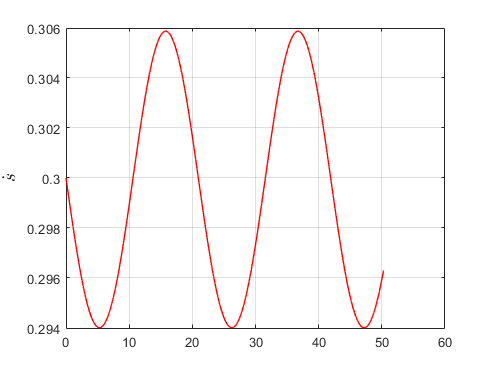

figure()
plot(T,V,'-r', LineWidth=1.0)
ylabel('$\dot{s}$',Interpreter='latex',FontSize=14)
grid on

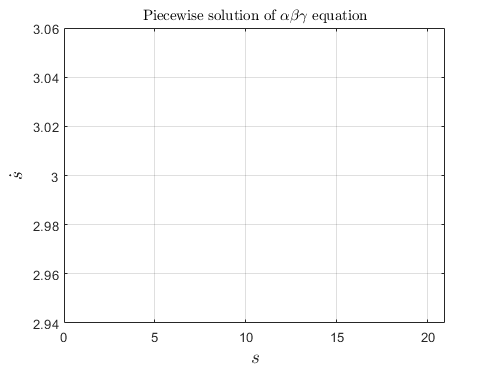


% t_idx = (T >= 0) & (T <= 2.1);
t_idx = (T >= 0) & (T <= 20.9501);

T = T(t_idx);
T = T - T(1);
S = S(t_idx);
V = V(t_idx);

% T = T(3:end-2);
% T = T - T(1);
% S = S(3:end-2);
% V = V(3:end-2);


figure()
plot(S, V, '-r', LineWidth=1.0)
xlabel('$s$',Interpreter='latex',FontSize=14)
ylabel('$\dot{s}$',Interpreter='latex',FontSize=14)
axis([T(1) T(end) 2.94 3.06 ])
grid on
title('Piecewise solution of $\alpha \beta \gamma$ equation','Interpreter','latex')

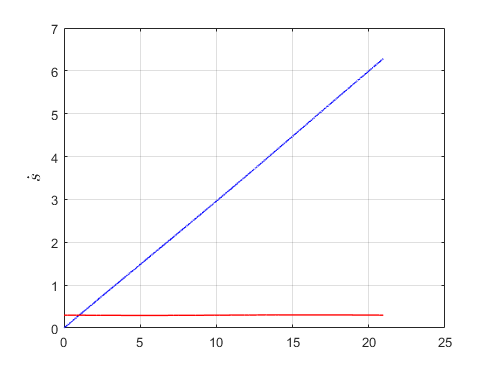


figure()
plot(T, S,'-b', LineWidth=1.0)
ylabel('$s$',Interpreter='latex',FontSize=14)
grid on
hold on
plot(T, V,'-r', LineWidth=1.0)
ylabel('$\dot{s}$',Interpreter='latex',FontSize=14)

## **Spline interpolation**

st = csaps(T,S);
vt = csaps(T,V);
T_per = T(end)

T_per =   20.949999999999999


**spline verification**

t = 0 : 0.01 : T_per;

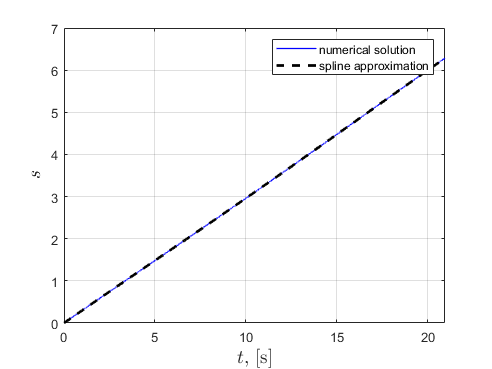

figure()
plot(T, S,'-b', LineWidth=1.0)
hold on
plot(t, ppval(st,t),'--k', LineWidth=2.0)
ylabel('$s$',Interpreter='latex',FontSize=14)
xlabel('$t$, [s]',Interpreter='latex',FontSize=14)
grid on
axis([ 0 t(end) 0 7])
legend('numerical solution','spline approximation')

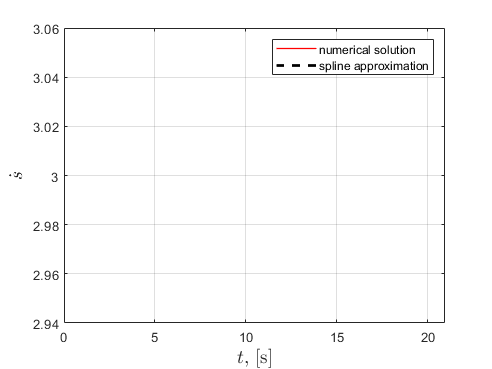


figure()
plot(T, V,'-r', LineWidth=1.0)
hold on
plot(t, ppval(vt,t),'--k', LineWidth=2.0)
ylabel('$\dot{s}$',Interpreter='latex',FontSize=14)
xlabel('$t$, [s]',Interpreter='latex',FontSize=14)
grid on
axis([ 0 t(end) 2.94 3.06])
legend('numerical solution','spline approximation')

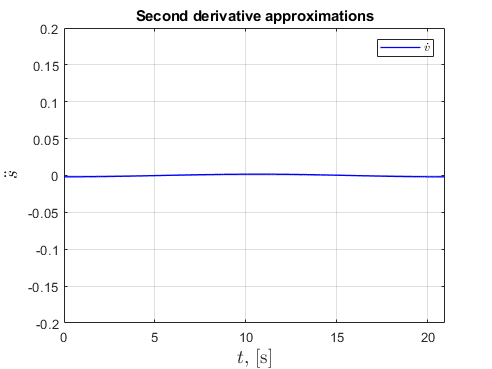


clear T Y

ddst = fnder(st, 2);
dvt  = fnder(vt, 1);


figure()
plot(t,ppval(dvt, t),'-b', LineWidth=1.0)
hold on
% plot(t,ppval(ddst, t),'-r', LineWidth=1.0)
ylabel('$\ddot{s}$',Interpreter='latex',FontSize=14)
xlabel('$t$, [s]',Interpreter='latex',FontSize=14)
axis([ 0 t(end) -0.2 0.2 ])
grid on
title("Second derivative approximations")
legend('$\dot{v}$','Interpreter','latex')

## **Find nominal control**

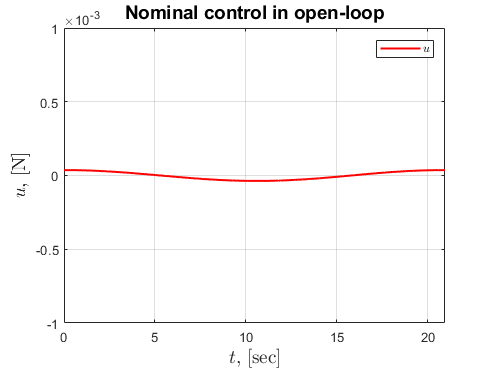

U = zeros(1,length(t));

for i = 1 : length(t)
    U(i) = find_u_eq(ppval(st,t(i)), ppval(vt,t(i)), ppval(dvt,t(i)), params);
end

pu = csaps(t,U);

figure()
plot(t, ppval(pu,t), '-r', LineWidth=1.5)

grid on
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$u$, [N]',Interpreter='latex',FontSize=14)
title('Nominal control in open-loop',FontSize=14);
legend('$u$','Interpreter','latex')
axis([ 0 t(end) -1e-3 1e-3 ])

## Simulation of full dynamics with nominal control

s0  = ppval(st, t(1))

s0 =      1.752051169788913e-10


ds0 = ppval(vt, t(1))

ds0 =    0.299999999999986



[ Q0, dQ0, ddQ0 ] = servo(s0, params);
y0 = [ Q0; dQ0 .* ds0]

y0 =     0.0000
    0.0010
    0.3000
   -0.0000


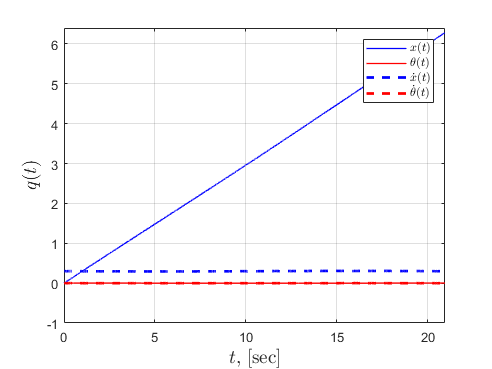



options_normal = odeset('RelTol', 1e-12, 'AbsTol', 1e-16);
[ TT, YY ] = ode89(@(t,y) true_system(t,y,pu,T_per, params), [0 t(end)], y0, options_normal);

figure()
plot(TT, YY(:,1),'-b',LineWidth=1.0)
hold on
plot(TT, YY(:,2),'-r',LineWidth=1.0)
plot(TT, YY(:,3),'--b',LineWidth=2.0)
plot(TT, YY(:,4),'--r',LineWidth=2.0)
grid on
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$q(t)$',Interpreter='latex',FontSize=14)
legend('$x(t)$','$\theta (t)$','$\dot{x}(t)$','$\dot{\theta}(t)$','Interpreter','latex')
axis([0 TT(end) -1 6.4])

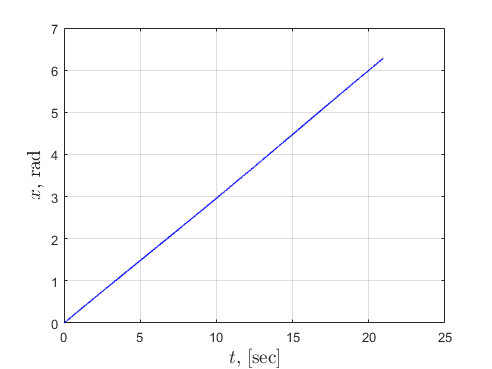





figure()
plot(TT, YY(:,1),'-b',LineWidth=1.0)
grid on
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$x$, rad',Interpreter='latex',FontSize=14)

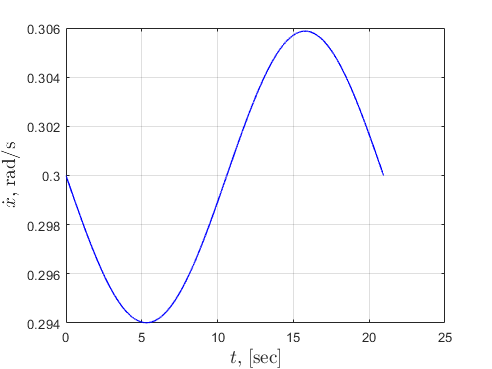


figure()
plot(TT, YY(:,3),'-b',LineWidth=1.0)
grid on
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$\dot{x}$, rad/s',Interpreter='latex',FontSize=14)

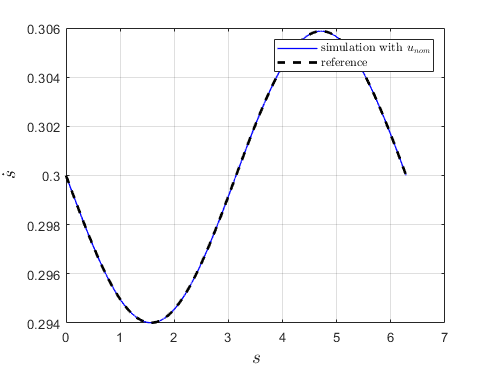


figure()
plot(YY(:,1), YY(:,3),'-b',LineWidth=1.0)
grid on
hold on
plot(ppval(st,t),ppval(vt,t),'--k',LineWidth=2.0)
xlabel('$s$',Interpreter='latex',FontSize=14)
ylabel('$\dot{s}$',Interpreter='latex',FontSize=14)
legend('simulation with $u_{nom}$','reference','Interpreter','latex')

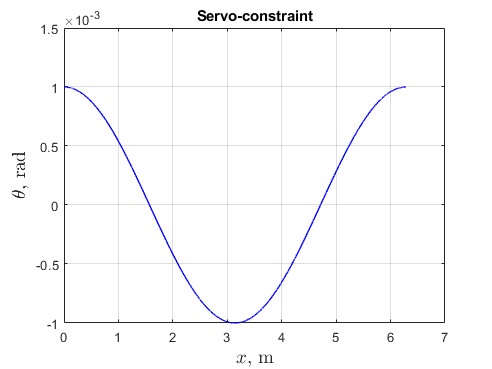


% figure()
% plot(YY(:,1), YY(:,3),'-b',LineWidth=1.0)
% grid on
% hold on
% xlabel('$x$',Interpreter='latex',FontSize=14)
% ylabel('$\dot{x}$',Interpreter='latex',FontSize=14)
% % xline(s_sing,'--k',LineWidth=0.5)
% legend('simulation with $u_{nom}$','Interpreter','latex')

figure()
plot(YY(:,1), YY(:,2),'-b',LineWidth=1.0)
grid on
hold on
xlabel('$x$, m',Interpreter='latex',FontSize=14)
ylabel('$\theta$, rad',Interpreter='latex',FontSize=14)
title('Servo-constraint')

## Trajectory Stabilization 

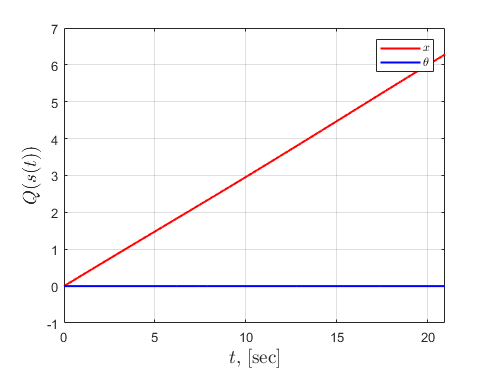

t_sample = 0.01;
t_sample_cr = 0.0005;

t = make_sampling(t_sample,t_sample_cr, T_per);

[ X, dX ] = from_MG_to_X(t, st, vt, dvt, params);

figure()
plot(t, X(1,:), '-r',LineWidth=1.5)
hold on
plot(t, X(2,:), '-b',LineWidth=1.5)
grid on
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$Q(s(t))$',Interpreter='latex',FontSize=14)
legend('$x$','$\theta$','Interpreter','latex')
axis([0 T_per -1 7])

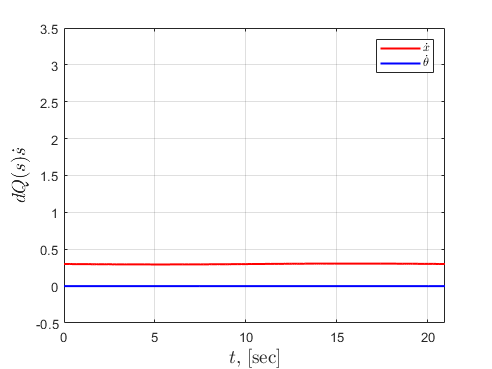


figure()
plot(t, dX(1,:), '-r',LineWidth=1.5)
hold on
plot(t, dX(2,:), '-b',LineWidth=1.5)
grid on
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$dQ(s)\dot{s}$',Interpreter='latex',FontSize=14)
legend('$\dot{x}$','$\dot{\theta}$','Interpreter','latex')
axis([0 T_per -0.5 3.5])


X_ref = [ csaps(t,X(1,:)); csaps(t,X(2,:)); csaps(t,X(3,:)); csaps(t,X(4,:)) ];
dX_ref = [ csaps(t,dX(1,:)); csaps(t,dX(2,:)); csaps(t,dX(3,:)); csaps(t,dX(4,:)) ];


**Step 3: **

**Transversal linearization: A(t) and B(t) formation**

MM = length(t);

AA = zeros(3, 3 * MM);
BB = zeros(3, MM);

AAA = zeros(3, MM);

[ g_y, g_dy, g_v] = g_fcn(params)

g_y = function_handle with value:
    @(dds,ds,s)cos(cos(s)./1.0e+3).*(-7.02396e-1)-sin(cos(s)./1.0e+3).*((dds.*sin(s))./1.0e+3+(ds.^2.*cos(s))./1.0e+3).*4.296e-3+dds.*sin(cos(s)./1.0e+3).*7.160000000000001e-2+ds.^2.*cos(cos(s)./1.0e+3).*sin(s).^2.*4.296e-9


g_dy = function_handle with value:
    @(ds,s)ds.*sin(cos(s)./1.0e+3).*sin(s).*(-8.592000000000001e-6)


g_v = function_handle with value:
    @(s)cos(cos(s)./1.0e+3).*(-4.296e-3)-1.7184e-3


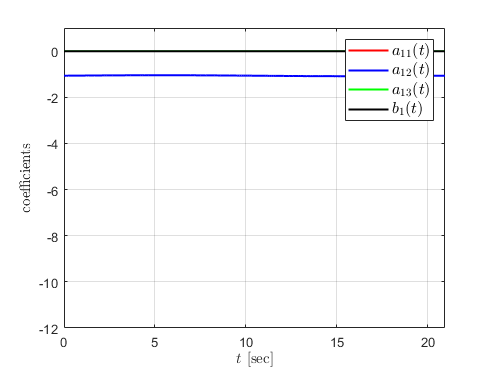


for i = 1 : MM

    [ alpha, beta, gamma ] = plot_abg(ppval(st, t(i)), params);

    AAA(:,i) = [ alpha, beta, gamma ]';

    AA(1, 1 + 3 * (i-1)) = - 2 * ppval(vt, t(i)) / alpha * beta;
    
    AA(1, 2 + 3 * (i-1)) =   2 * ppval(vt, t(i)) / alpha *  g_y(ppval(dvt, t(i)), ppval(vt, t(i)), ppval(st, t(i)));
    
    AA(1, 3 + 3 * (i-1)) =   2 * ppval(vt, t(i)) / alpha * g_dy(ppval(vt, t(i)), ppval(st, t(i)));

    AA(2, 3 + 3 * (i-1)) =   1;


    BB(1, i) = 2 * ppval(vt, t(i)) / alpha * g_v(ppval(st, t(i)));
    
    BB(3, i) = 1;

end
figure()
plot(t, AA(1,1:3:end),'-r',LineWidth=1.5)
hold on
plot(t, AA(1,2:3:end),'-b',LineWidth=1.5)
plot(t, AA(1,3:3:end),'-g',LineWidth=1.5)

plot(t, BB(1,:),'-k',LineWidth=1.5)
grid on

xlabel('$t$ [sec]',Interpreter='latex',FontSize=11)
ylabel('coefficients',Interpreter='latex',FontSize=11)
% axis([-2.1 -2.07 0.75 2])
legend('$a_{11}(t)$','$a_{12}(t)$','$a_{13}(t)$','$b_1(t)$','FontSize',12,'interpreter','latex')
axis([0 t(end) -12 1 ])

**Step 4: **

**Controller design for **$\dot{\mathbf{\xi}}=\mathbf{A}(t) \mathbf{\xi} + \mathbf{B}(t)\bar{u}$

P = sdpvar(3,3,'symmetric','real');

w = 2 * pi / T_per;
   
Q = 100*diag([10,1,5]);
R = 1;


M = 31;

for j = 1:M
    P = [P; sdpvar(3,3,'sy','co')];
end

PP = zeros(3);
DP = zeros(3);
i = sqrt(-1);
L = [];

for j = 0 : length(t) - 1
    for k = 1:M
        PP = PP + exp(i*(-k)*w*t(j+1)) * conj( P(1+3*k:3*k + 3, 1:3) ) + exp(i*k*w*t(j+1))*P(1+3*k:3*k + 3, 1:3);
        DP = DP + (i*(-k)*w)*exp(i*(-k)*w*t(j+1)) * conj( P(1+3*k:3*k + 3, 1:3) ) + (i*k*w)*exp(i*k*w*t(j+1)) * P(1+3*k:3*k + 3, 1:3);
    end
    
    PP = PP + P(1:3,1:3);
    L11 = DP + PP * AA( :, (1 + 3*j):(3 + 3*    j) ) + AA( :, (1 + 3*j):(3 + 3*j) )' * PP + Q;
    L12 = PP * BB( :, j+1 );
    L21 = BB( :, j+1 )' * PP;
    L22 = R;
    L = [ L, [L11 L12; L21 L22] >= 0 ];
    PP = zeros(3);
    DP = zeros(3);
end

F = trace(P(1:3,1:3));
optimize(L, -F);


 num. of constraints = 378
 dim. of sdp    var  = 8384,   num. of sdp  blk  = 2096
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.2e+04|1.5e+00|9.4e+07| 3.355696e+07  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.950|6.5e-03|7.4e-02|6.3e+06| 4.764431e+06  1.213898e-01| 0:0:01| chol  1  1 
 2|0.957|0.977|2.5e-04|3.0e-03|3.8e+05| 3.467946e+05  1.139443e+00| 0:0:01| chol  1  1 
 3|0.997|1.000|7.5e-06|6.6e-05|1.8e+04| 1.785899e+04  1.886453e+01| 0:0:02| chol  1  1 
 4|0.860|1.000|1.3e-06|3.1e-06|3.2e+03| 3.463396e+03  3.035086e+02| 0:0:02| chol  1  1 
 5|1.000|0.568|2.6e-07|1.7e-06|2.3e+03| 3.997768e+03  1.662195e+0

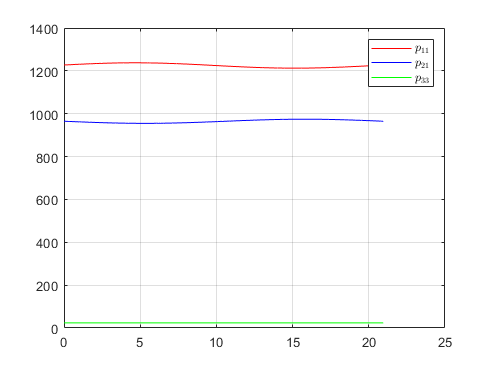

P_s = value(P);

PP = zeros(3);
DP = zeros(3);
P_final = [];

for j = 0 : length(t) - 1
    for k = 1:M
        PP = PP + exp(i*(-k)*w*t(j+1)) * conj( P_s(1+3*k:3*k + 3, 1:3) ) + exp(i*k*w*t(j+1)) * P_s(1+3*k:3*k + 3, 1:3);
        DP = DP + (i*(-k)*w)*exp(i*(-k)*w*t(j+1)) * conj( P_s(1+3*k:3*k + 3, 1:3) ) + (i*k*w)*exp(i*k*w*t(j+1)) * P_s(1+3*k:3*k + 3, 1:3);
    end
    PP = PP + P_s(1:3,1:3);

    P_final = [P_final; PP];
    PP = zeros(3);
    DP = zeros(3);
end

P_final((end-2):end,:) = P_final(1:3,:);


figure()
plot(t, P_final(1:3:end,1),'-r')
hold on
plot(t, P_final(2:3:end,2),'-b')
plot(t, P_final(3:3:end,3),'-g')
grid on
legend('$p_{11}$','$p_{21}$','$p_{33}$','Interpreter','latex')

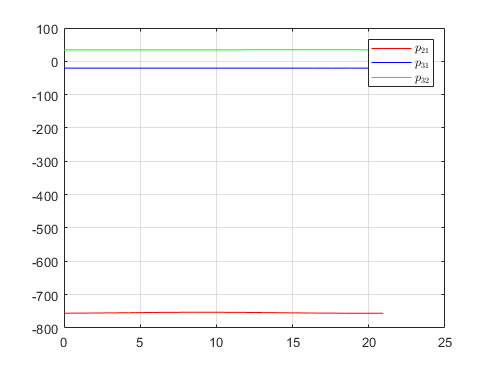


figure()
plot(t, P_final(2:3:end,1),'-r')
hold on
plot(t, P_final(3:3:end,1),'-b')
plot(t, P_final(3:3:end,2),'-g')
grid on
legend('$p_{21}$','$p_{31}$','$p_{32}$','Interpreter','latex')

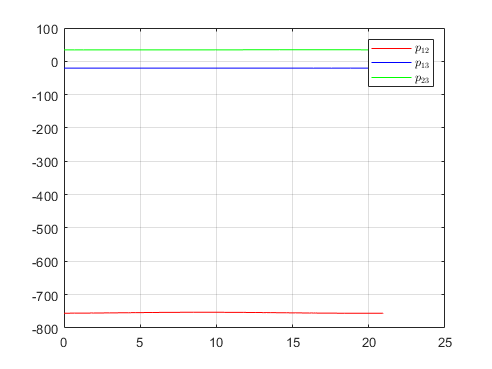


figure()
plot(t, P_final(1:3:end,2),'-r')
hold on
plot(t, P_final(1:3:end,3),'-b')
plot(t, P_final(2:3:end,3),'-g')
grid on
legend('$p_{12}$','$p_{13}$','$p_{23}$','Interpreter','latex')

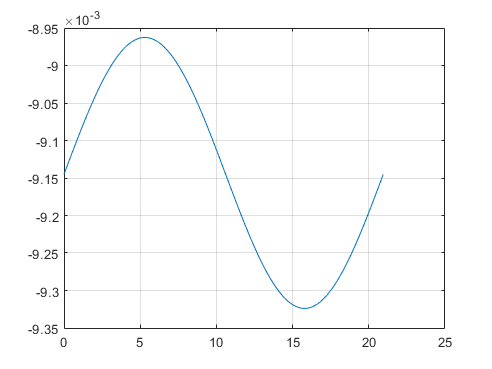



K_stab = zeros(length(t)-1,3);
figure()
plot(t,BB(1,1:end))
grid on

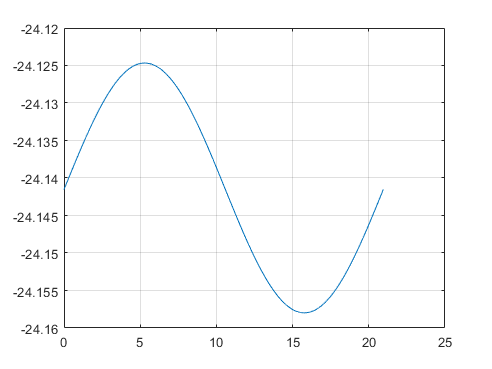

kb = zeros(1,length(t));

for i = 1 : length(t)
   
    K_stab(i,1:3) = - (1 / R) .* (((BB(:,i))' * P_final(1 + 3 * (i - 1):3*i,1:3)));
    kb(i) = K_stab(i,1:3) * BB(:,i);
end

figure()
plot(t,kb)
grid on

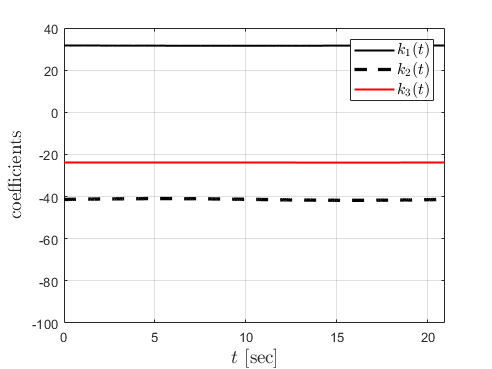


figure()
plot(t(1:end),K_stab(:,1),'-k',LineWidth=1.5)
hold on
plot(t(1:end),K_stab(:,2),'--k',LineWidth=2.5)
plot(t(1:end),K_stab(:,3),'-r',LineWidth=1.5)
grid on
xlabel('$t$ [sec]',Interpreter='latex',FontSize=14)
ylabel('coefficients',Interpreter='latex',FontSize=14)
% axis([-2.1 -2.07 0.75 2])
% legend('$a_1(t)$','$b_1(t)$','FontSize',11,'interpreter','latex')
axis([0 t(end) -100 40 ])
legend('$k_1(t)$','$k_2(t)$','$k_3(t)$','FontSize',12,'Interpreter','latex')

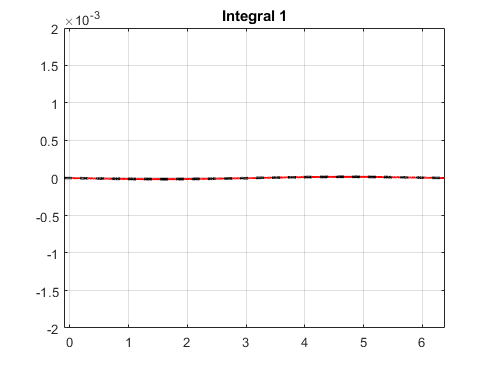

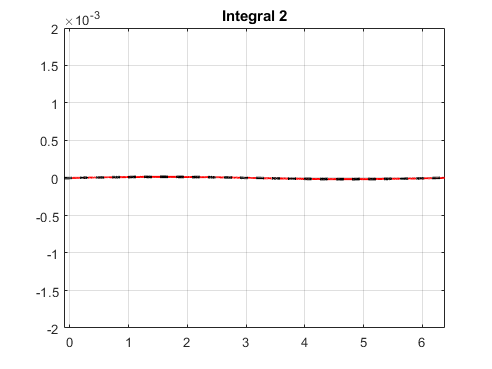

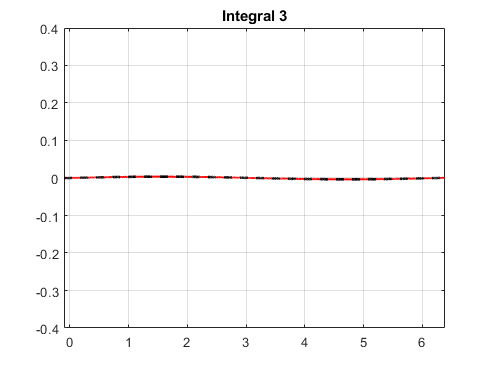

I_main = function_handle with value:
    @(q,dq)dq^2-exp(-2.*ppval(I_1_fcn,q))*(X_starr_0(2)^2-ppval(I_3_fcn,q))



k_1 = spline(t,K_stab(:,1));
k_2 = spline(t,K_stab(:,2));
k_3 = spline(t,K_stab(:,3));


X_starr_0 = [ ppval(st, 0); ppval(vt, 0) ];


[ I_main ] = calc_I_fcn_tr(X_starr_0, params)


I_main(X_starr_0(1), X_starr_0(2))

ans =      0


I_main(X_starr_0(1), X_starr_0(2) + 2)

ans =    5.199999999999944


I_main(9.8, 8)

ans =   63.896841883090978




X_0 = [ 9.8; 8 ];
t_0 = 0.6;
X_per = X(1,end);

[ tau, X_star, min_dist_fin ] = proj_fcn_cylinder(t, 0, X_0, X, X_ref, 0.2*T_per, T_per, X_per)

tau =    4.190000000000000


X_star =     1.2433
    0.0003
    0.2943
   -0.0003


min_dist_fin =    7.705667391290954


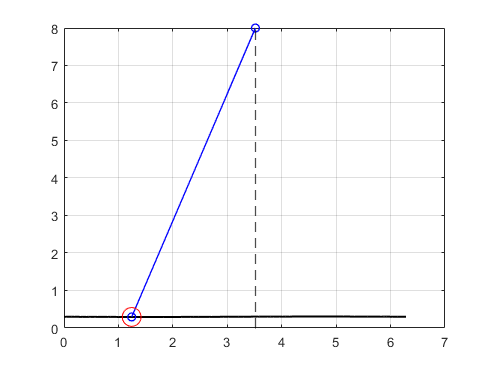

figure()
plot(X(1,:), X(3,:), '-k', LineWidth=1.5)
hold on
plot( [ mod(X_0(1), X_per), X_star(1) ], [ X_0(2), X_star(3)], '-ob',LineWidth=1.0)
scatter(X_star(1,:), X_star(3,:), 200, 'red')
grid on
xline(mod(X_0(1), X_per), '--k', LineWidth=1.0)

**Step 5: **

**Dynamics simulation **

U_fcn = u2v_transformation(params)

U_fcn = function_handle with value:
    @(theta,theta_dot,v,x,x_dot,z)(v.*6.350436595912277e+42-v.*cos(theta).^2.*1.916540739582502e+42+v.*cos(theta).*1.177762465665225e+42+z.*sin(theta).*1.509878097318436e+45-x_dot.^2.*z.*cos(x).*6.350436595912277e+39-theta_dot.^2.*z.*sin(theta).*5.888812328326124e+41+z.*sin(theta).*sin(x).*5.776924894087928e+39+theta_dot.^2.*z.*sin(theta.*2.0).*9.582703697912512e+41-x_dot.^2.*z.*cos(theta).*cos(x).*1.177762465665225e+39-theta_dot.^2.*z.*sin(theta).*sin(x).*8.132985171993679e+37-z.*cos(theta).*sin(theta).*sin(x).*1.880126465530435e+40+x_dot.^2.*z.*cos(theta).^2.*cos(x).*1.916540739582502e+39)./(cos(theta).*7.435369101421874e+45-sin(x).*1.784488584341249e+41-cos(theta).*sin(x).*4.461221460853124e+41+3.354223770613499e+46)


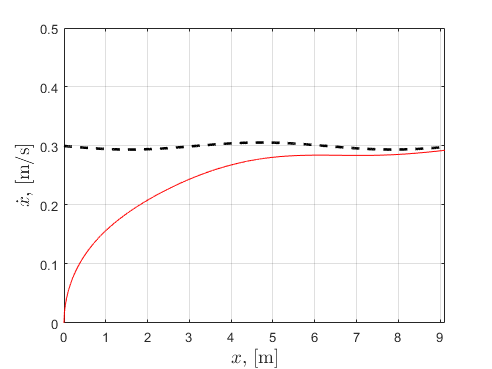


% X_0 = 0.9 * from_t_to_vector4(0, X_ref)
X_0 = [ 0 0 0 0];



% [ tau_0, X_star_0, min_dist_0 ] = proj_fcn_cylinder(t, 0, [ X_0(1); X_0(3) ], X(1:2:end,:), X_ref, 1.0 * T_per, T_per, X_per)

% X_0 = zeros(4, 1);

KKK = [k_1, k_2, k_3];

h_step = 1e-3;

T_sim = 2.1 * T_per;

TT = 0 : h_step : T_sim;
N = length(TT);

YY = zeros(4,N);
Tau = zeros(1,N);
UU_nom = zeros(1,N);
UU_fb = zeros(1,N);
dd = zeros(1,N);
Xi = zeros(3,N);
WW = zeros(1,N);

[ tau_0, X_star_0, min_dist_0 ] = proj_fcn_cylinder(t, 0, [ X_0(1); X_0(3) ], X(1:2:end,:), X_ref, 0.2 * T_per, T_per, X_per);

xi_0 = calc_tran_coord_s(X_0, X_star_0, I_main, params, X_per);

Tau(1) = tau_0;
YY(:,1) = X_0;
Xi(:,1) = xi_0; 


for i = 2 : N
    ddq = controlled_system(YY(:,i-1), t, Tau(i-1), X, X_ref, pu, KKK, T_per, 0.1*T_per, X_per, U_fcn, I_main, params);
    YY(:,i) = YY(:,i-1) + h_step .* ddq(1:4);
    Tau(i) = ddq(5);
    UU_nom(i) = ddq(7);
    WW(i) = ddq(8);
    Xi(:,i) = ddq(9:11);
    UU_fb(i) = ddq(6);
end


figure()
plot(YY(1,:), YY(3,:), 'r')
hold on
plot(YY(1,:), ppval(X_ref(3),mod(Tau,T_per)), '--k', LineWidth=2.0)
xlabel('$x$, [m]',Interpreter='latex',FontSize=14)
ylabel('$\dot{x}$, [m/s]', Interpreter='latex',FontSize=14)
grid on
axis([0 YY(1,end) 0 0.5])

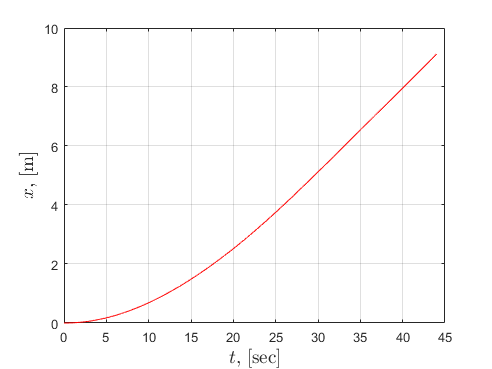

% axis([0 YY(1,end) 0 3.5])


figure()
plot(TT, YY(1,:), 'r')
grid on
% axis([0 TT(end) 0 50])
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$x$, [m]',Interpreter='latex',FontSize=14)

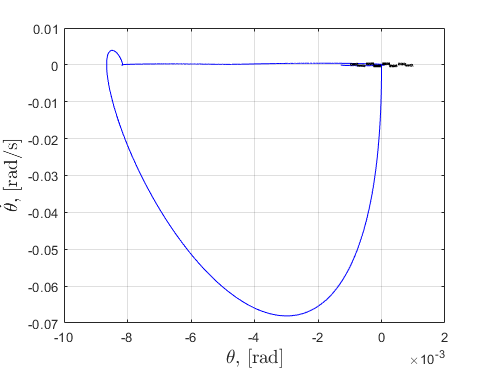


% figure()
% plot(TT, YY(3,:), 'r')
% grid on
% axis([0 TT(end) 0 3.5])
% xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
% ylabel('$\dot{x}$, [m/s]',Interpreter='latex',FontSize=14)

figure()
plot(YY(2,:), YY(4,:), 'b')
hold on
plot(X(2,:), X(4,:), '--k', LineWidth=2.0)
grid on
xlabel('$\theta$, [rad]',Interpreter='latex',FontSize=14)
ylabel('$\dot{\theta}$, [rad/s]', Interpreter='latex',FontSize=14)

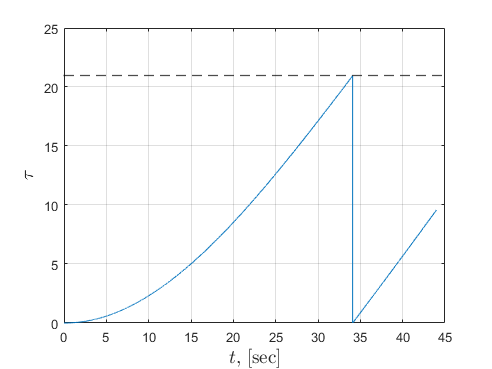

% axis([-0.5 0.13 -5 1])


figure()
title("Prohection operator")
plot(TT,Tau)
hold on
yline(T_per,'--k',LineWidth=1.0)
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$\tau$',Interpreter='latex',FontSize=14)
grid on

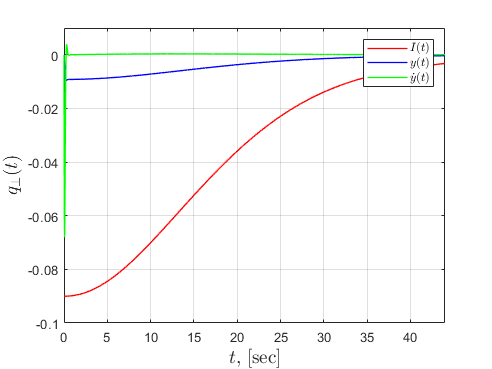

% axis([0 TT(end) 0 2.2])

figure()
plot(TT, Xi(1,:), '-r', LineWidth=1.0)
hold on
plot(TT, Xi(2,:), '-b', LineWidth=1.0)
plot(TT, Xi(3,:), '-g', LineWidth=1.0)
grid on
legend('$I(t)$', '$y(t)$','$\dot{y}(t)$','Interpreter','latex')
% axis([0 TT(end) -10 2])
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$q_\perp(t)$',Interpreter='latex',FontSize=14)
axis([0 TT(end) -0.1 0.01])

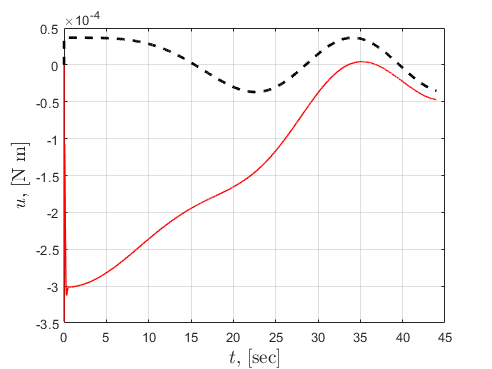


figure()
plot(TT, UU_fb, '-r', LineWidth=1.0)
hold on
plot(TT, UU_nom, '--k', LineWidth=2.0)
% plot(TT,ppval(pu,mod(Tau,T_per)),'--k',LineWidth=2.0)
grid on
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$u$, [N m]',Interpreter='latex',FontSize=14)

% axis([0 TT(end) -0.025 0.005])

% figure()
% plot(X(1,:), X(3,:), '--k', LineWidth=2.0)
% hold on
% grid on
% scatter(4.71451,3.054121,20,'red')
% scatter(mod(11.0093,X_per),3.0533,20,'blue')
% scatter(mod(17.3089,X_per),3.05243,20,'green')
% scatter(mod(23.6095,X_per),3.05161,20,'magenta')



